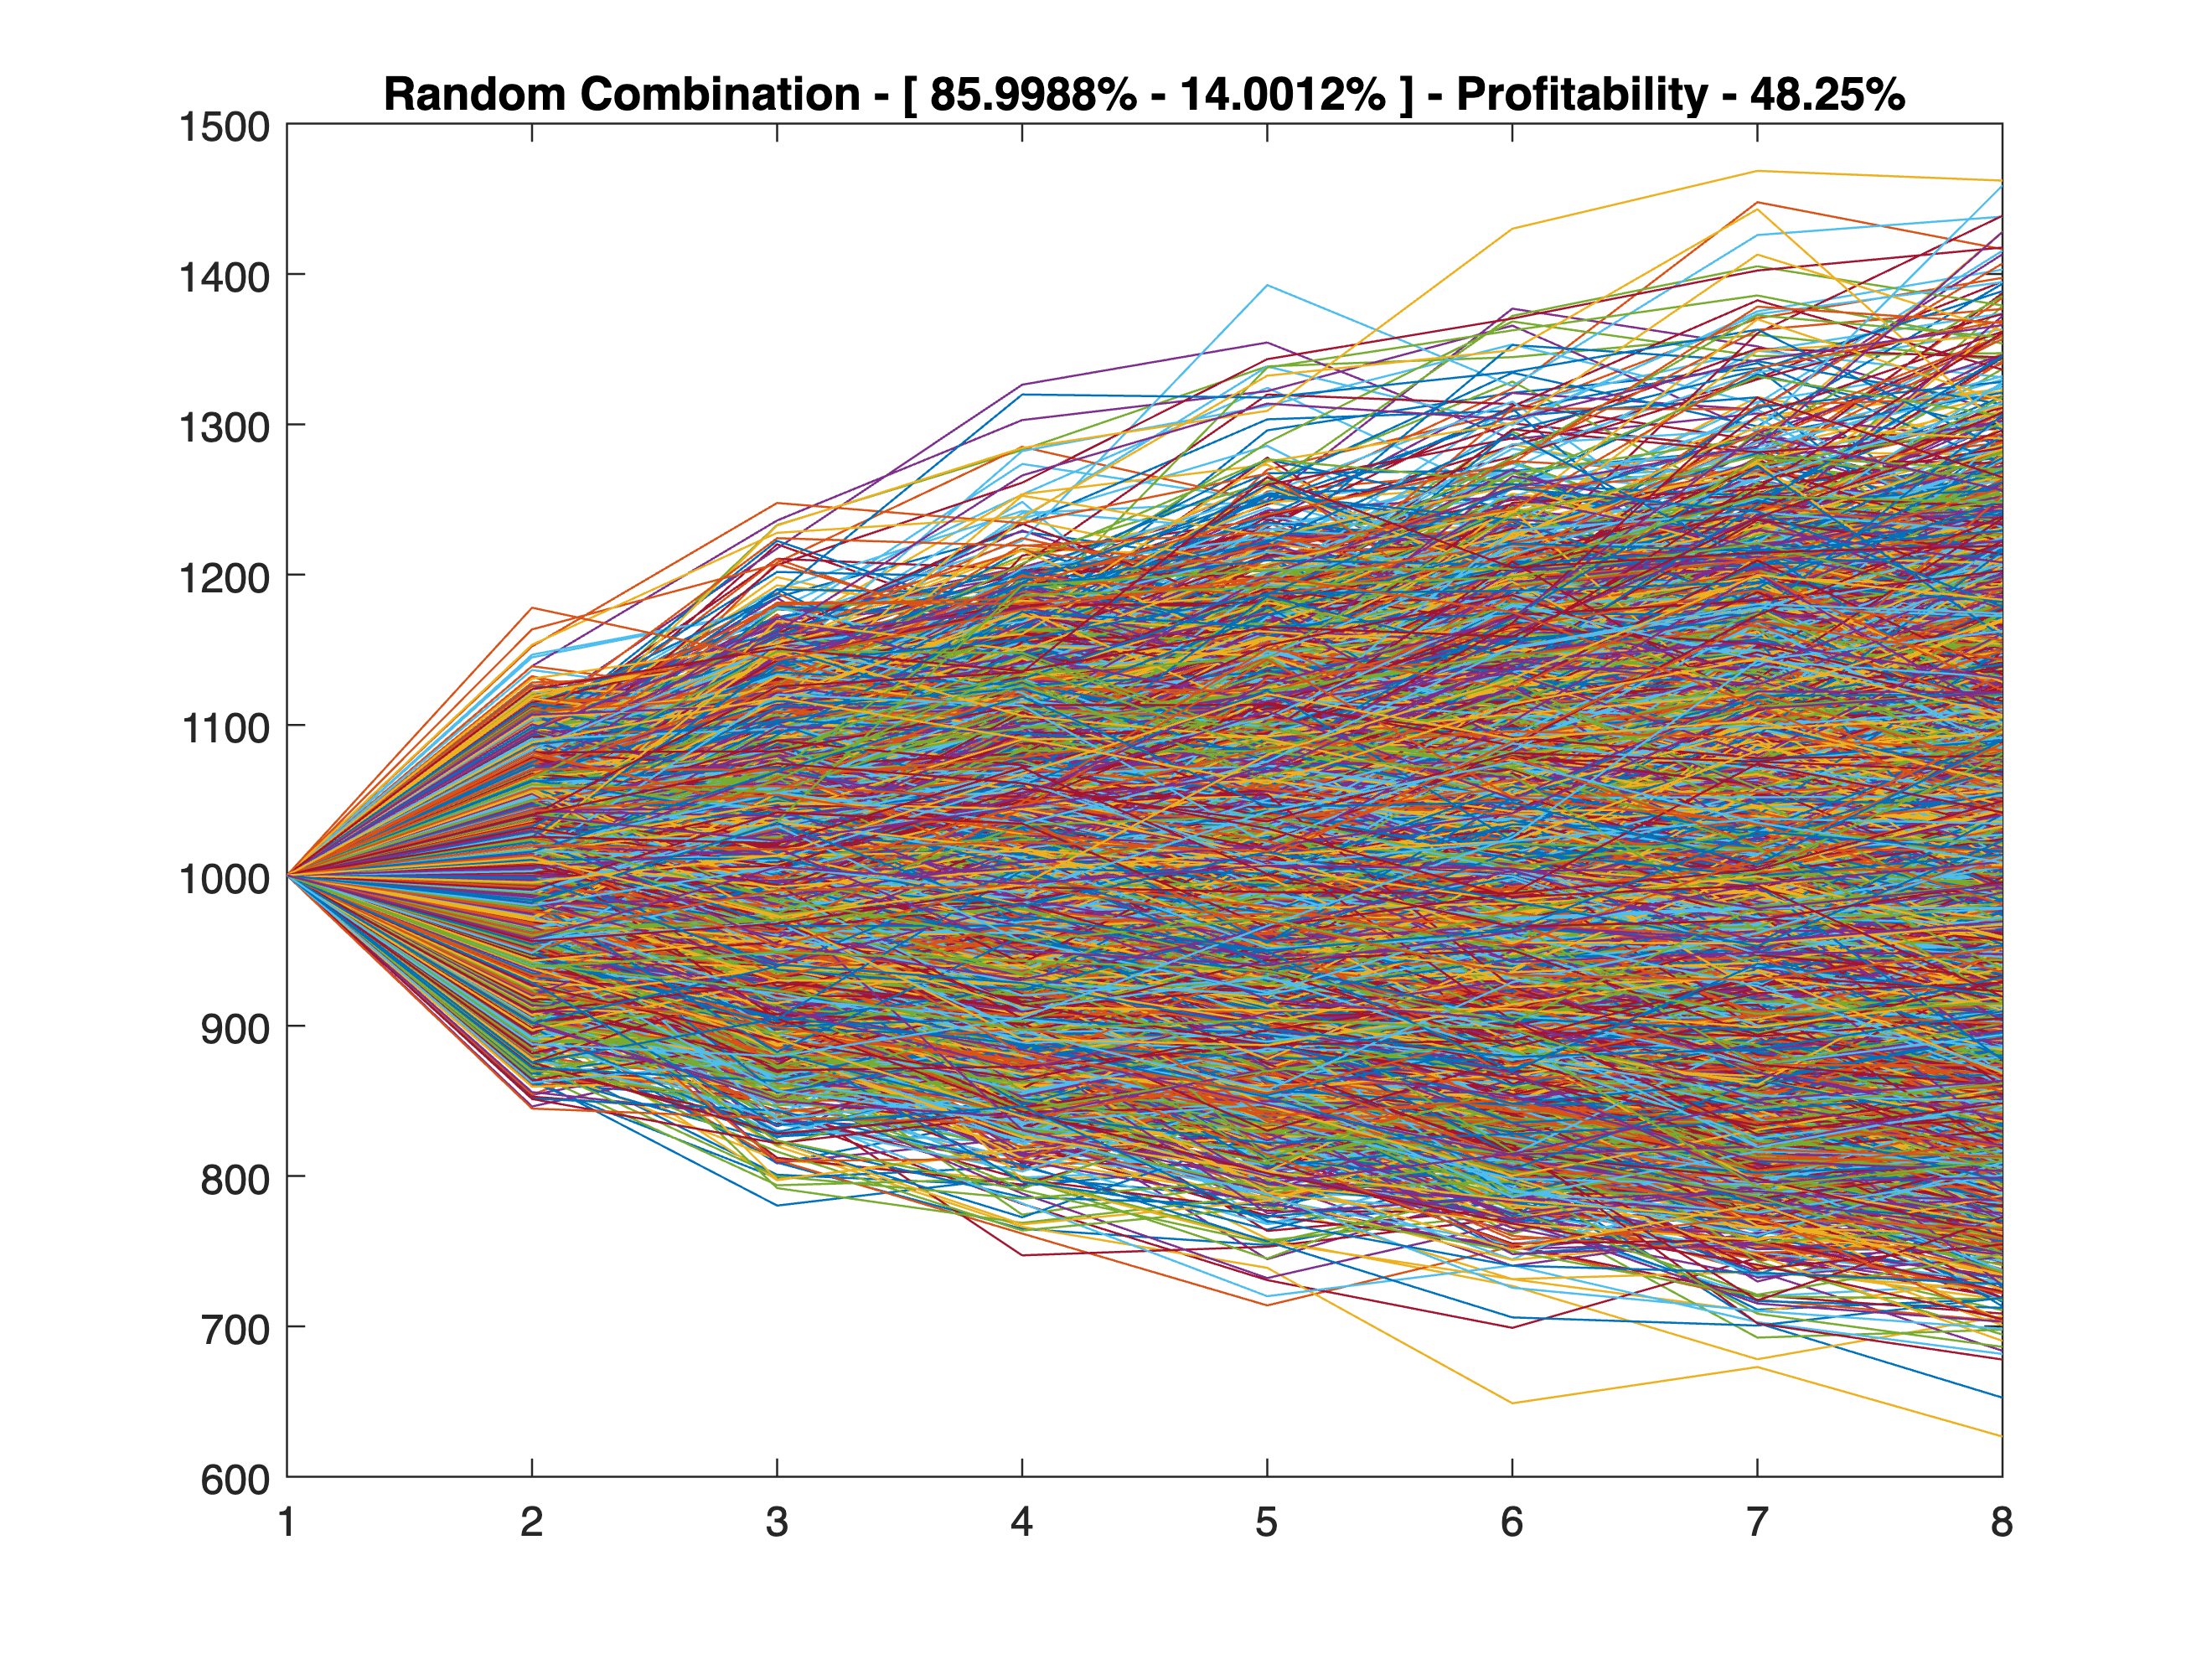

% Portfolio Risk Management - Working Example - MATLAB Version

% N stands for the number of combinations available
% M stands for the number of assets considered for the simulation
% K stands for the number of simulation
% D stands for the number of days considered
% C stands for the initial capital

N = 2;
M = 2;
D = 7;
K = 10000;
C = 1000;

coefficients = zeros(N, M); % Let's create a Matrix N*M
B = normrnd(0, 0.05, M, D, K); % We assume normally distributed returns with 0 mean and 0.05 standard deviation, we create a tensor by MxDxK dimensions

% We are now creating the convex linear combinations (each row will sum up to 1)
for i = 1:N
    weights = 0;
    combination = zeros(1, M);
    for j = 1:M - 1
        w_ = unifrnd(0, 1 - weights, 1);
        combination(j) = w_;
        weights = weights + w_;
    end
    combination(M) = 1 - weights;
    coefficients(i, :) = combination;
end

returns = 1 + tensorprod(coefficients, B, 2, 1); % We are multiplyng the Matrix composed by the convex linear combinations by the returns tensor B 
cumulative_returns = cumprod(returns, 2); % We cumulate the returns
cumulative_results = C.*cumulative_returns; % We set the initial capital
last_time = cumulative_results(:, end, :); % We consider all the returns on the last day

%Plotting a random combination of coefficient
random_comb = randi([1 N], 1, 1);
for i = 1:K
    plot([C cumulative_results(random_comb, :, i)]);
    hold on;
end
title("Random Combination - [ " + coefficients(random_comb, 1) * 100 + "% - " + coefficients(random_comb, 2) * 100 + "% ] - Profitability - " + length(find(last_time(random_comb, :, :) > C)) / K * 100 + "%");